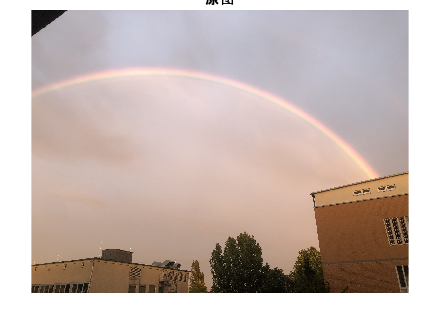

clear
close all
img = imread('E:\Matlab数字图像处理程序\IMG_4208.jpg');
%figure()
imshow(img)
title('原图')

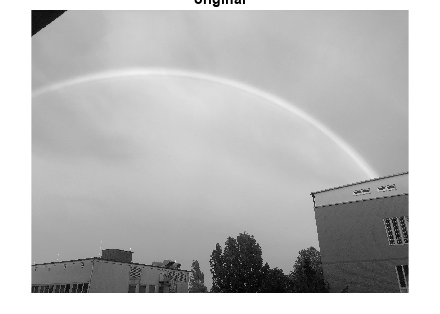


[R,G,B]=imsplit(img);

grayimage = rgb2gray(img);


%%
%对总的灰度进行直方图均衡

%figure()
imshow(grayimage);
title('original')

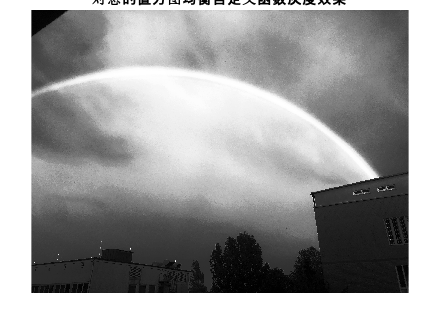


[rownumber,columnnumber,~]=size(img);

grayscalenum = zeros(1,256);

for i = 0:1:255
    for row = 1:rownumber
        for column = 1:columnnumber
            if grayimage(row,column) == i
                grayscalenum(i+1) = grayscalenum(i+1) + 1;
            end
        end
    end
end

pixelamount = rownumber * columnnumber;

newgrayscale = zeros(1,256);


b=255;
a=0;

for i = 0:1:255
    for j = 0:1:i
        newgrayscale(i+1) = (b-a) * (sum(grayscalenum(1:(j+1))))/pixelamount;
    end
end



for row = 1:rownumber
    for column = 1:columnnumber
        grayimage(row,column) = newgrayscale(grayimage(row,column)+1);
    end
end

imshow(grayimage)
title('对总的直方图均衡自定义函数灰度效果')

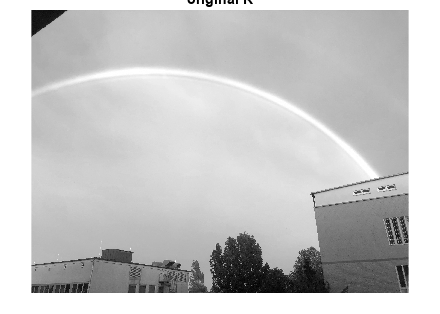


%%
%对R通道进行直方图均衡
%figure()
imshow(R);
title('original R')

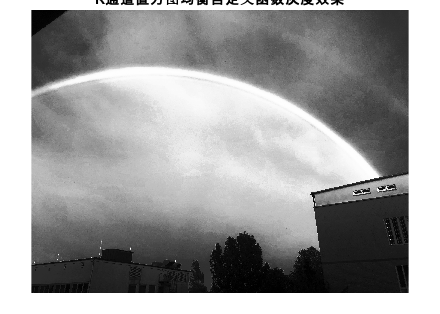


[rownumber,columnnumber,pages]=size(img);

Rgrayscalenum = zeros(1,256);

for i = 0:1:255
    for row = 1:rownumber
        for column = 1:columnnumber
            if R(row,column) == i
                Rgrayscalenum(i+1) = Rgrayscalenum(i+1) + 1;
            end
        end
    end
end

pixelamount = rownumber * columnnumber;

rnewgrayscale = zeros(1,256);


b=255;
a=0;

for i = 0:1:255
    for j = 0:1:i
        rnewgrayscale(i+1) = (b-a) * (sum(Rgrayscalenum(1:(j+1))))/pixelamount;
    end
end



for row = 1:rownumber
    for column = 1:columnnumber
        R(row,column) = rnewgrayscale(R(row,column)+1);
    end
end

imshow(R)
title('R通道直方图均衡自定义函数灰度效果')

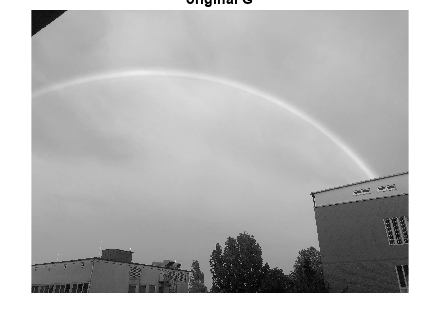


%%
%对G通道进行直方图均衡
%figure()
imshow(G);
title('original G')

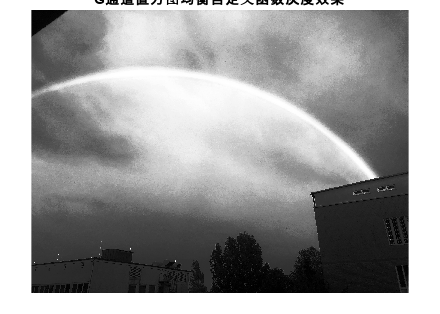


[rownumber,columnnumber,pages]=size(img);

Ggrayscalenum = zeros(1,256);

for i = 0:1:255
    for row = 1:rownumber
        for column = 1:columnnumber
            if G(row,column) == i
                Ggrayscalenum(i+1) = Ggrayscalenum(i+1) + 1;
            end
        end
    end
end

pixelamount = rownumber * columnnumber;

rnewgrayscale = zeros(1,256);


b=255;
a=0;

for i = 0:1:255
    for j = 0:1:i
        gnewgrayscale(i+1) = (b-a) * (sum(Ggrayscalenum(1:(j+1))))/pixelamount;
    end
end



for row = 1:rownumber
    for column = 1:columnnumber
        G(row,column) = gnewgrayscale(G(row,column)+1);
    end
end

imshow(G)
title('G通道直方图均衡自定义函数灰度效果')

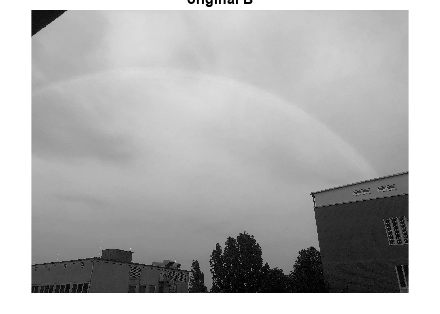



%%
%对B通道进行直方图均衡
%figure()
imshow(B);
title('original B')

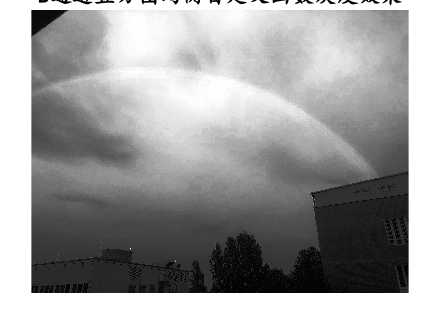


[rownumber,columnnumber,pages]=size(img);

Bgrayscalenum = zeros(1,256);

for i = 0:1:255
    for row = 1:rownumber
        for column = 1:columnnumber
            if B(row,column) == i
                Bgrayscalenum(i+1) = Bgrayscalenum(i+1) + 1;
            end
        end
    end
end

pixelamount = rownumber * columnnumber;

rnewgrayscale = zeros(1,256);


b=255;
a=0;

for i = 0:1:255
    for j = 0:1:i
        bnewgrayscale(i+1) = (b-a) * (sum(Bgrayscalenum(1:(j+1))))/pixelamount;
    end
end



for row = 1:rownumber
    for column = 1:columnnumber
        B(row,column) = bnewgrayscale(B(row,column)+1);
    end
end

imshow(B)
title('B通道直方图均衡自定义函数灰度效果','FontName','楷体','FontSize',16)

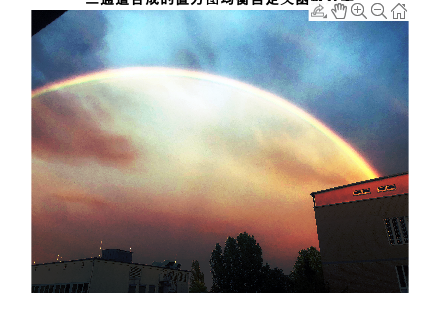


%%
%三通道的合成
imagecolor(:,:,1) = R;
imagecolor(:,:,2) = G;
imagecolor(:,:,3) = B;

%figure
imshow(imagecolor)
title('三通道合成的直方图均衡自定义函数效果')

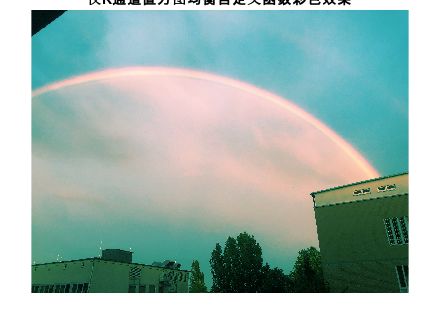


%%
%三通道的合成，仅R通道直方图均衡
[~,G,B]=imsplit(img);
imagecolor(:,:,1) = R;
imagecolor(:,:,2) = G;
imagecolor(:,:,3) = B;

figure
imshow(imagecolor)
title('仅R通道直方图均衡自定义函数彩色效果')

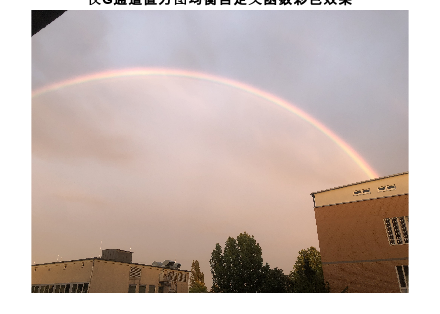




%%
%三通道的合成，仅G通道直方图均衡
[R,~,B]=imsplit(img);
imagecolor(:,:,1) = R;
imagecolor(:,:,2) = G;
imagecolor(:,:,3) = B;

%figure
imshow(imagecolor)
title('仅G通道直方图均衡自定义函数彩色效果')

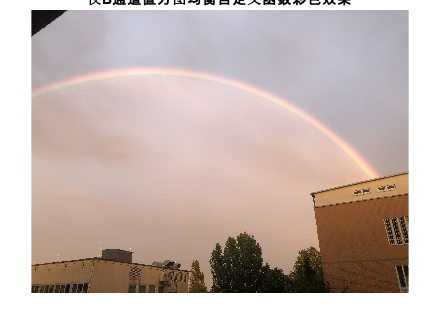

%%
%三通道的合成，仅B通道直方图均衡
[R,G,~]=imsplit(img);
imagecolor(:,:,1) = R;
imagecolor(:,:,2) = G;
imagecolor(:,:,3) = B;

%figure
imshow(imagecolor)
title('仅B通道直方图均衡自定义函数彩色效果')